# Audio Filterng

clear;clc;

load("r2112.mat");
sound(rush,FS);

## FFT Power Spectral Density

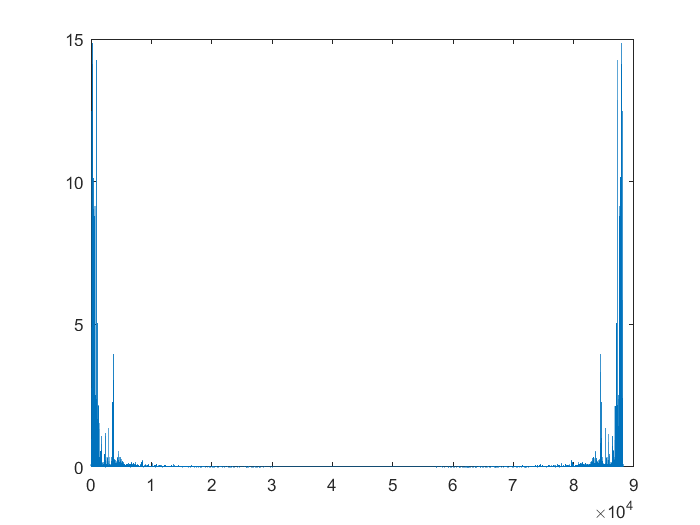

rush_k = fft(rush);
N = length(rush);
PSD = rush_k.*conj(rush_k)/N;
plot((1:N)-1,PSD);

## Load Noisy Data

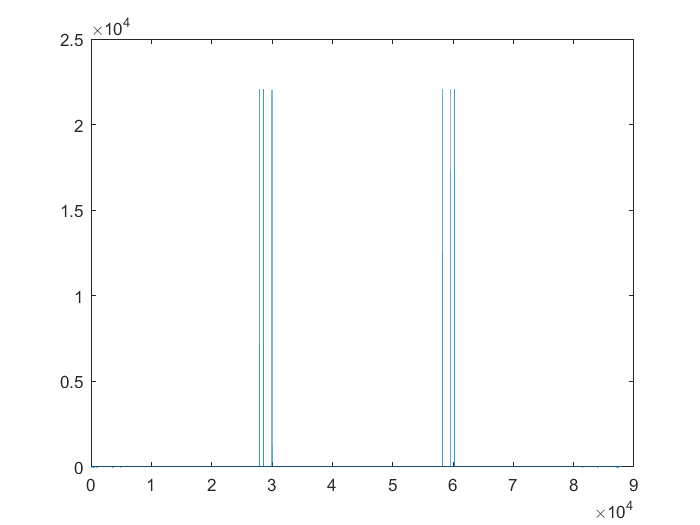

load("r2112noisy.mat");
sound(rushnoisy,FS);
rushnoisy_k = fft(rushnoisy);
N = length(rushnoisy);
noisyPSD = rushnoisy_k.*conj(rushnoisy_k)/N;
plot((1:N)-1,noisyPSD);

## Filter Noisy Data

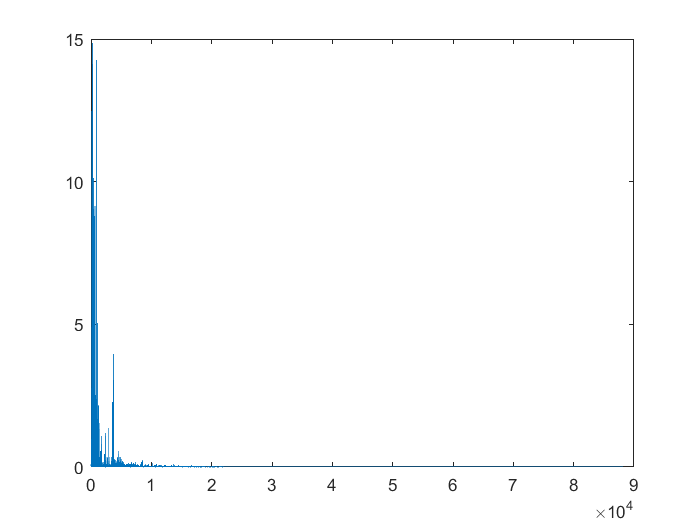

rushclean_k = rushnoisy_k;
rushclean_k(N/4:N) = 0;
rushclean = 2*real(ifft(rushclean_k));
sound(rushclean,FS);
cleanPSD = rushclean_k.*conj(rushclean_k)/N;
plot((1:N)-1,cleanPSD);